首先修改工作文件夹到有数据的那个文件夹

clear; clc
cd 'C:\Users\sxjmqf\Desktop\机器学习进阶课程\4.房价预测'

**导入数据**

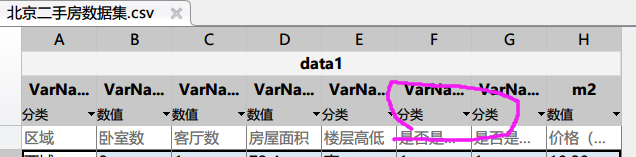

%% 初始化变量。
filename = '北京二手房数据集.csv';
delimiter = ',';
startRow = 2;
formatSpec = '%C%f%f%f%C%C%C%f%[^\n\r]';
%% 打开文本文件。
fileID = fopen(filename,'r');
dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'TextType', 'string', 'EmptyValue', NaN, 'HeaderLines' ,startRow-1, 'ReturnOnError', false, 'EndOfLine', '\r\n');
fclose(fileID);
data1 = table(dataArray{1:end-1}, 'VariableNames', {'VarName1','VarName2','VarName3','VarName4','VarName5','VarName6','VarName7','m2'});
clearvars filename delimiter startRow formatSpec fileID dataArray ans;

**返回表中各个指标的信息**

summary(data1)


Variables:

    VarName1: 10000×1 categorical

        Values:

            东城     1762      
            丰台     1797      
            朝阳     1725      
            海淀     1789      
            石景山    1218      
            西城     1709      

    VarName2: 10000×1 double

        Values:

            Min       1         
            Median    2         
            Max       5         

    VarName3: 10000×1 double

        Values:

            Min       0         
            Median    1         
            Max       3         

    VarName4: 10000×1 double

        Values:

            Min        29.3     
            Median     78.8     
            Max       300.7     

    VarName5: 10000×1 categorical

        Values:

            中    3440      
            低    3122      
            高    3438      

    VarName6: 10000×1 categorical

        Values:

            0    1701 

**线性回归模型（带交互项）：**

trainingData = data1;
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4', 'VarName5', 'VarName6', 'VarName7'};
predictors = inputTable(:, predictorNames);
response = inputTable.m2;
isCategoricalPredictor = [true, false, false, false, true, true, true];

% Train a regression model
% This code specifies all the model options and trains the model.
concatenatedPredictorsAndResponse = predictors;
concatenatedPredictorsAndResponse.m2 = response;
linearModel = fitlm(...
    concatenatedPredictorsAndResponse, ...
    'interactions', ...
    'RobustOpts', 'off');

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
linearModelPredictFcn = @(x) predict(linearModel, x);
trainedModel.predictFcn = @(x) linearModelPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedModel.RequiredVariables = {'VarName1', 'VarName2', 'VarName3', 'VarName4', 'VarName5', 'VarName6', 'VarName7'};
trainedModel.LinearModel = linearModel;
trainedModel.About = 'This struct is a trained model exported from Regression Learner R2017a.';
trainedModel.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4', 'VarName5', 'VarName6', 'VarName7'};
predictors = inputTable(:, predictorNames);
response = inputTable.m2;
isCategoricalPredictor = [true, false, false, false, true, true, true];

% Perform cross-validation
KFolds = 5;
cvp = cvpartition(response, 'KFold', KFolds);

警告:0ne or more folds do not contain points from all the groups.

出现这个警告的原因没有在MATLAB官网查到，不过不影响最后的结果，可以忽略


% Initialize the predictions to the proper sizes
validationPredictions = response;
for fold = 1:KFolds
    trainingPredictors = predictors(cvp.training(fold), :);
    trainingResponse = response(cvp.training(fold), :);
    foldIsCategoricalPredictor = isCategoricalPredictor;
    
    % Train a regression model
    % This code specifies all the model options and trains the model.
    concatenatedPredictorsAndResponse = trainingPredictors;
    concatenatedPredictorsAndResponse.m2 = trainingResponse;
    linearModel = fitlm(...
        concatenatedPredictorsAndResponse, ...
        'interactions', ...
        'RobustOpts', 'off');
    
    % Create the result struct with predict function
    linearModelPredictFcn = @(x) predict(linearModel, x);
    validationPredictFcn = @(x) linearModelPredictFcn(x);
    
    % Add additional fields to the result struct
    
    % Compute validation predictions
    validationPredictors = predictors(cvp.test(fold), :);
    foldPredictions = validationPredictFcn(validationPredictors);
    
    % Store predictions in the original order
    validationPredictions(cvp.test(fold), :) = foldPredictions;
end

% Compute validation RMSE
validationRMSE = sqrt(nansum(( validationPredictions - response ).^2) / numel(response));

% 交叉验证后得到的测试集上的衡量指标
isNotMissing = ~isnan(validationPredictions) & ~isnan(response);
format long g  % 数值显示的精度变高
validationSSE = sum(( validationPredictions - response ).^2,'omitnan') ;
validationMSE = sum(( validationPredictions - response ).^2,'omitnan') / numel(response(isNotMissing));
validationRMSE = sqrt(sum(( validationPredictions - response ).^2,'omitnan') / numel(response(isNotMissing) ));
validationMAE = sum(abs( validationPredictions - response),'omitnan') / numel(response(isNotMissing));
validationMAPE = sum(abs((validationPredictions - response)./response),'omitnan') / numel(response(isNotMissing));
validationSMAPE = sum(abs(validationPredictions - response)./((abs(response)+abs(validationPredictions))/2),'omitnan') / numel(response(isNotMissing));
validationR2 = 1 -  sum(( validationPredictions - response ).^2,'omitnan') / sum((response - mean(response,'omitnan')).^2,'omitnan');
validation_result = table(validationSSE,validationMSE,validationRMSE,validationMAE,validationMAPE,validationSMAPE,validationR2)

validation_result = 1×7 table
     validationSSE        validationMSE       validationRMSE       validationMAE       validationMAPE       validationSMAPE       validationR2   
    ________________    _________________    ________________    _________________    _________________    _________________    _________________

    7418.25273377242    0.741825273377242    0.86129279189904    0.704567623643028    0.109142822313259    0.107319533358059    0.803896402536964


format short % 恢复默认显示的精度

**关于R方**$:R^2$**（拟合优度\决定系数\可决系数）**

[https://ww2.mathworks.cn/help/stats/coefficient-of-determination-r-squared.html](https://ww2.mathworks.cn/help/stats/coefficient-of-determination-r-squared.html)

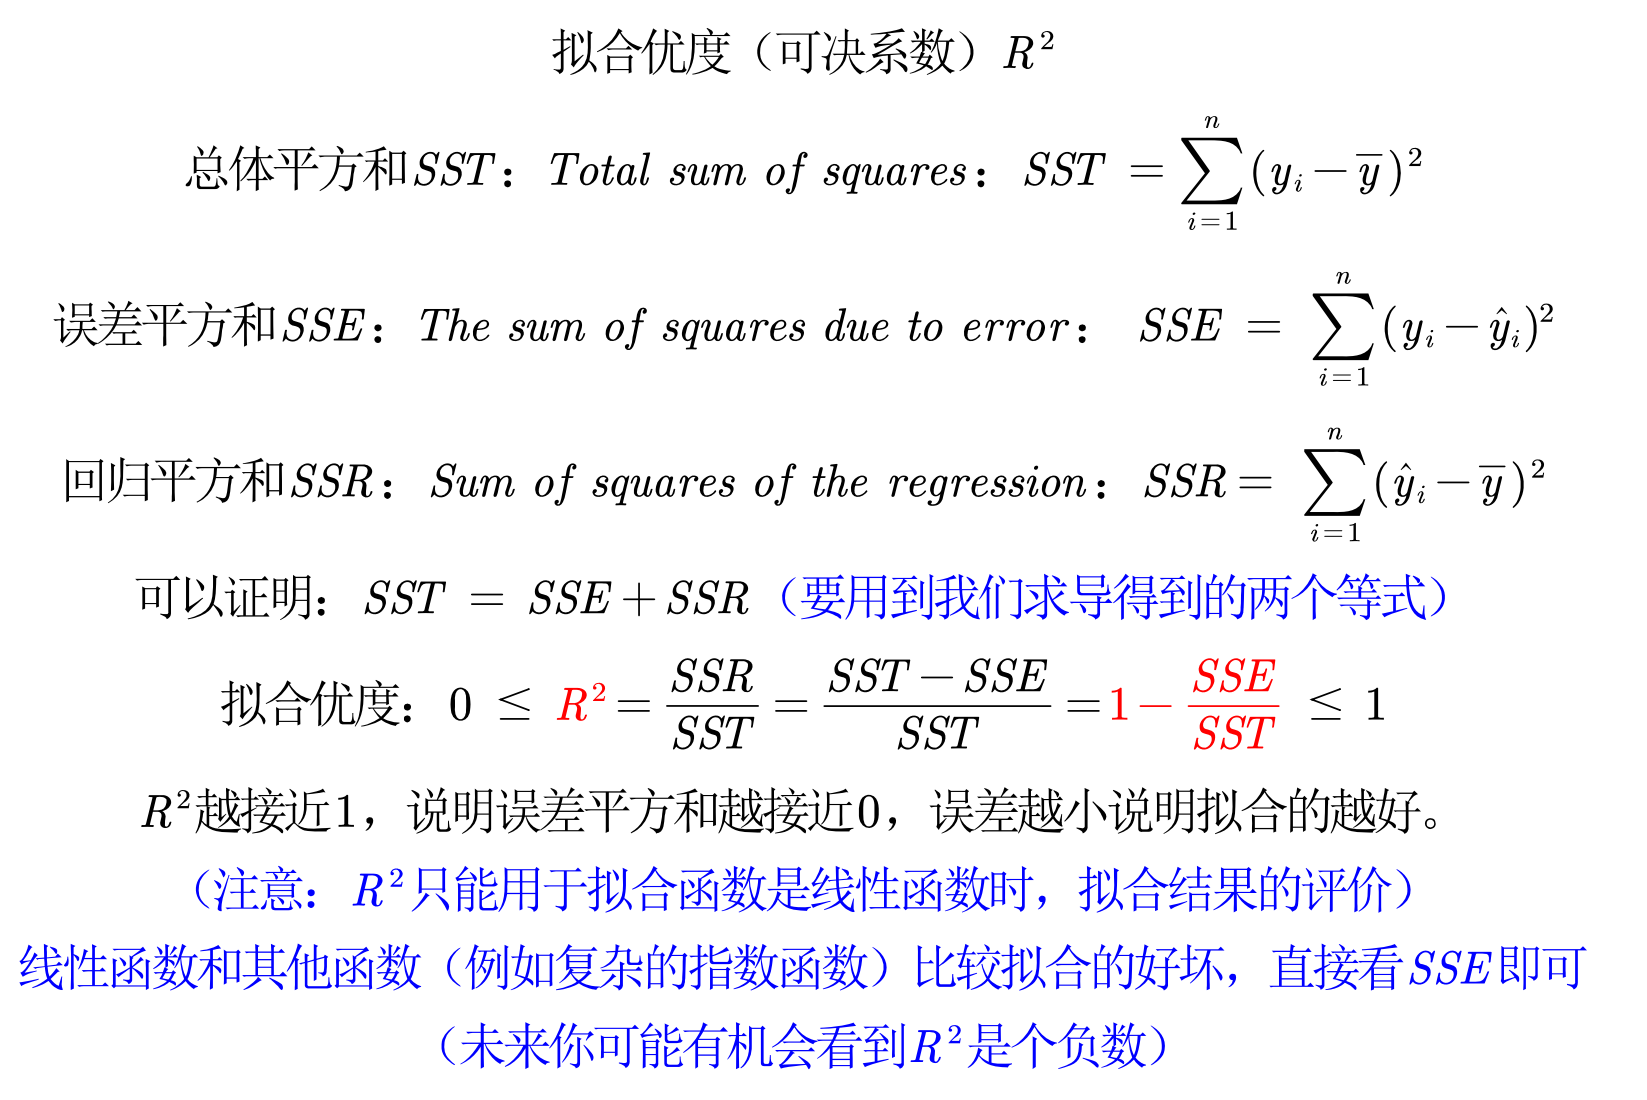

注意，在拟合中我们说的有点太绝对了，事实上在非线性场合，R方也可以衡量拟合结果的好坏。

**但是一定要注意，此时SST=SSE+SSR不再成立，计算R方的公式只能使用**$1-\frac{\mathrm{SSE}}{\mathrm{SST}}$**，**

**它的范围也不再是位于[0,1]之间，而是位于**$\left(-\infty ,1\right\rbrack$**.**

**R方越接近1，说明预测的效果越好。**

**如果R方为负数，说明你的模型的预测效果很差，不推荐使用这个模型。**

在机器学习中，我们可以用R方衡量测试集上模型的好坏。

注意，如果你使用了交叉验证，例如上面我们的例子中，我们使用的5折交叉验证。

那么最终得到的测试集包含所有的样本，且是由五个模型的测试集组成的。

即使原来每个模型都是线性的，例如上面我们交叉验证时用的是线性回归，我们最终得到的这个总体的测试集上的R方仍然有可能为负数。

大家如果有兴趣，可以随机生成一些数据进行测试。

% 查看所有数据训练出来的线性模型（这个就是我们之前介绍的回归模型，里面的分类变量当成虚拟变量处理）
trainedModel.LinearModel  % （注意，这是使用所有的样本来训练得到的模型，不区分训练组和测试组）

ans = 
Linear regression model:
    m2 ~ 1 + VarName1*VarName2 + VarName1*VarName3 + VarName1*VarName4 + VarName1*VarName5 + VarName1*VarName6 + VarName1*VarName7 + VarName2*VarName3 + VarName2*VarName4 + VarName2*VarName5 + VarName2*VarName6 + VarName2*VarName7 + VarName3*VarName4 + VarName3*VarName5 + VarName3*VarName6 + VarName3*VarName7 + VarName4*VarName5 + VarName4*VarName6 + VarName4*VarName7 + VarName5*VarName6 + VarName5*VarName7 + VarName6*VarName7

Estimated Coefficients:
                                Estimate         SE          tStat        pValue   
                               __________    __________    _________    ___________

    (Intercept)                    5.8701       0.15097       38.882    5.8659e-308
    VarName1_丰台                   -1.3254        0.1393      -9.5144      2.254e-21
    VarName1_朝阳                  -0.96524       0.15017      -6.4276     1.3556e-10
    VarName1_海淀                   0.53528       0.14079        3.802     0.00014441
    Var

% 我验算了下，上面表中，MATLAB计算的均方根误差的分母用的是残差的自由度（回归分析里面的概念）

我这里就偷个懒，不调参了，课后大家可以自己试试调参。

我这里直接预测，先导入要预测的数据

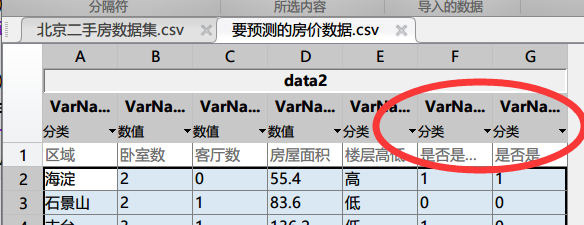

%% 初始化变量。
filename = '要预测的房价数据.csv';
delimiter = ',';
startRow = 2;
formatSpec = '%C%f%f%f%C%C%C%[^\n\r]';

%% 打开文本文件。
fileID = fopen(filename,'r','n','UTF-8');
% 跳过 BOM (字节顺序标记)。
fseek(fileID, 3, 'bof');

%% 根据格式读取数据列。
% 该调用基于生成此代码所用的文件的结构。如果其他文件出现错误，请尝试通过导入工具重新生成代码。
dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'TextType', 'string', 'HeaderLines' ,startRow-1, 'ReturnOnError', false, 'EndOfLine', '\r\n');

%% 关闭文本文件。
fclose(fileID);

%% 对无法导入的数据进行的后处理。
% 在导入过程中未应用无法导入的数据的规则，因此不包括后处理代码。要生成适用于无法导入的数据的代码，请在文件中选择无法导入的元胞，然后重新生成脚本。

%% 创建输出变量
data2 = table(dataArray{1:end-1}, 'VariableNames', {'VarName1','VarName2','VarName3','VarName4','VarName5','VarName6','VarName7'});

%% 清除临时变量
clearvars filename delimiter startRow formatSpec fileID dataArray ans;

用上面这个带有交互项的线性回归模型进行预测

predict_y = trainedModel.predictFcn(data2)  

predict_y =     8.5766
    4.2321
    4.7551
    5.9336
    5.6251
    8.5782
    9.8779
    7.6668
    5.2749
    6.6731


**使用随机森林**

trainingData = data1;
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4', 'VarName5', 'VarName6', 'VarName7'};
predictors = inputTable(:, predictorNames);
response = inputTable.m2;
isCategoricalPredictor = [true, false, false, false, true, true, true];

% Train a regression model
% This code specifies all the model options and trains the model.
template = templateTree(...
    'MinLeafSize', 8);
regressionEnsemble = fitrensemble(...
    predictors, ...
    response, ...
    'Method', 'Bag', ...
    'NumLearningCycles', 30, ...
    'Learners', template);

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
ensemblePredictFcn = @(x) predict(regressionEnsemble, x);
trainedModel.predictFcn = @(x) ensemblePredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedModel.RequiredVariables = {'VarName1', 'VarName2', 'VarName3', 'VarName4', 'VarName5', 'VarName6', 'VarName7'};
trainedModel.RegressionEnsemble = regressionEnsemble;
trainedModel.About = 'This struct is a trained model exported from Regression Learner R2017a.';
trainedModel.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4', 'VarName5', 'VarName6', 'VarName7'};
predictors = inputTable(:, predictorNames);
response = inputTable.m2;
isCategoricalPredictor = [true, false, false, false, true, true, true];

% Perform cross-validation
partitionedModel = crossval(trainedModel.RegressionEnsemble, 'KFold', 5);

% Compute validation predictions
validationPredictions = kfoldPredict(partitionedModel);

% Compute validation RMSE
validationRMSE = sqrt(kfoldLoss(partitionedModel, 'LossFun', 'mse'))

validationRMSE = 0.8277

validationRMSE = sqrt(kfoldLoss(partitionedModel, 'LossFun', 'mse'))

% 交叉验证后得到的测试集上的衡量指标
isNotMissing = ~isnan(validationPredictions) & ~isnan(response);
format long g  % 数值显示的精度变高
validationSSE = sum(( validationPredictions - response ).^2,'omitnan') ;
validationMSE = sum(( validationPredictions - response ).^2,'omitnan') / numel(response(isNotMissing));
validationRMSE = sqrt(sum(( validationPredictions - response ).^2,'omitnan') / numel(response(isNotMissing) ));
validationMAE = sum(abs( validationPredictions - response),'omitnan') / numel(response(isNotMissing));
validationMAPE = sum(abs((validationPredictions - response)./response),'omitnan') / numel(response(isNotMissing));
validationSMAPE = sum(abs(validationPredictions - response)./((abs(response)+abs(validationPredictions))/2),'omitnan') / numel(response(isNotMissing));
validationR2 = 1 -  sum(( validationPredictions - response ).^2,'omitnan') / sum((response - mean(response,'omitnan')).^2,'omitnan');
validation_result = table(validationSSE,validationMSE,validationRMSE,validationMAE,validationMAPE,validationSMAPE,validationR2)

validation_result = 1×7 table
     validationSSE        validationMSE       validationRMSE        validationMAE       validationMAPE       validationSMAPE       validationR2   
    ________________    _________________    _________________    _________________    _________________    _________________    _________________

    6850.40302405474    0.685040302405474    0.827671615077788    0.682643462466223    0.105803036236596    0.103951007558962    0.818907669325841


format short

使用随机森林进行预测

predict_y = trainedModel.predictFcn(data2)

predict_y =     8.5776
    4.1231
    4.8209
    5.8022
    5.7086
    8.6687
    9.8849
    7.6715
    5.6475
    6.6070


返回指标重要性

importance =oobPermutedPredictorImportance(regressionEnsemble);
 % 可以将重要性归一化到[0 1]区间内  % https://ww2.mathworks.cn/matlabcentral/answers/783611-need-predictor-importance-in-random-forest-expressed-as-a-percentage#answer_671247
importance(importance<0) = 0;
importance = importance./sum(importance)

importance =     0.4225    0.0741    0.0887    0.0977    0.0462    0.1281    0.1428


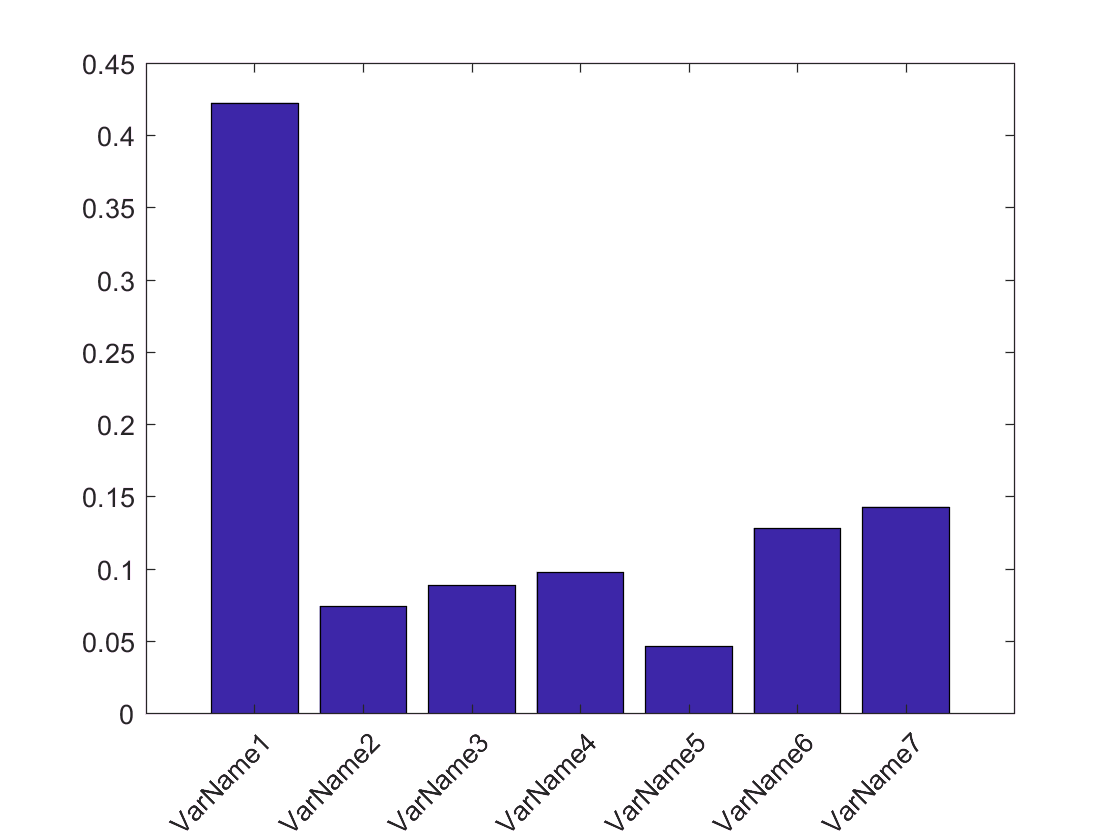

% 画一个柱状图
figure(1)
h_bar = bar(importance);
h_bar.Parent.XTickLabel =predictors.Properties.VariableNames;  
h_bar.Parent.XTickLabelRotation = 45;  
h_bar.Parent.TickLabelInterpreter =  'none';

% 提取出大于某个阈值重要性的指标
threshold = 1/length(importance);  % 阈值默认为:1除以指标个数
ind = predictors.Properties.VariableNames(importance>threshold)

ind = cell
    'VarName1'


这是使用的默认的命名看着不方便。。。

你可以在excel里面把指标名称改为英文，这样MATLAB导入数据的时候可以识别。

也可以自己修改图上的名称，例如：

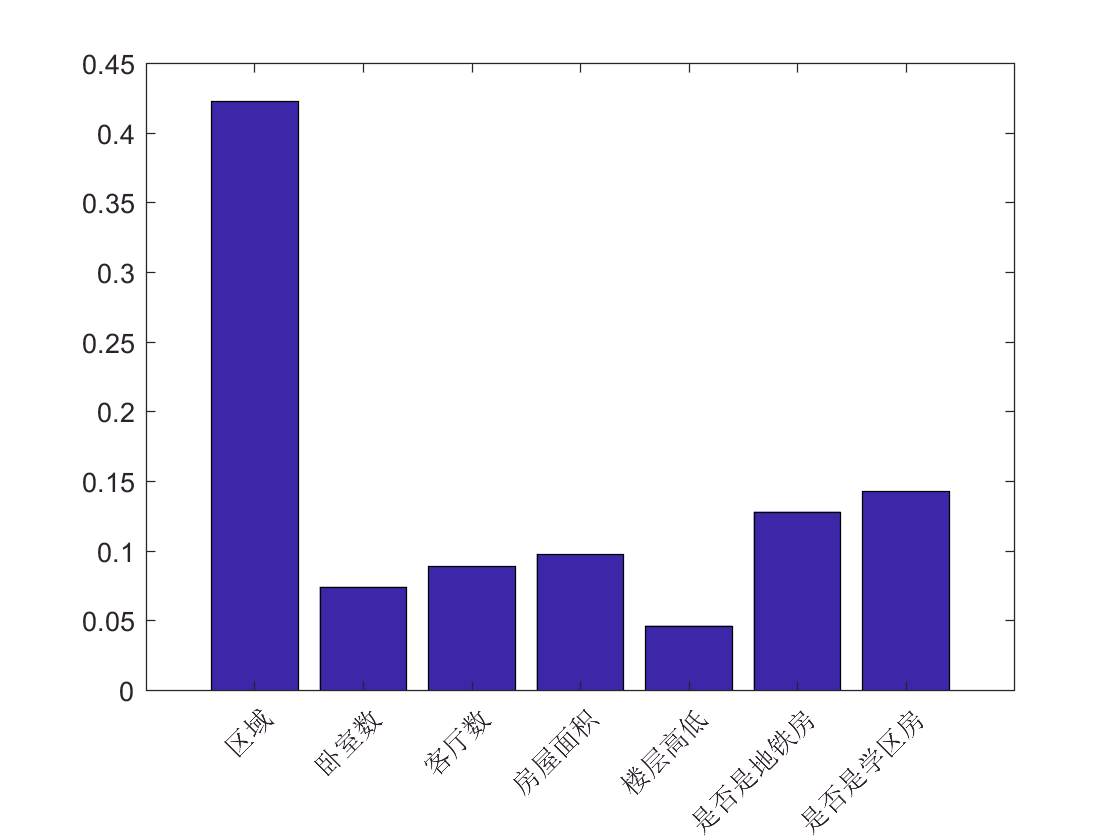

figure(2)
h_bar = bar(importance);
h_bar.Parent.XTickLabel ={'区域','卧室数','客厅数','房屋面积','楼层高低','是否是地铁房','是否是学区房'};
h_bar.Parent.XTickLabelRotation = 45;  
h_bar.Parent.TickLabelInterpreter =  'none';